% hawkes_vol_model.m
% Save to: C:\Users\zhaop\OneDrive\Desktop\project\hawkes_vol_model.m
% Data: coinbase_tick_large.csv (80,000 BTC tick trades)
% Innovation: sigma^2(t) = sigma^2_base + gamma * lambda(t)

clear; clc; close all;

BASE = 'C:\Users\zhaop\OneDrive\Desktop\project\';
RES  = [BASE 'results\'];

fprintf('=========================================\n');

fprintf('  Hawkes-Vol Model\n');

  Hawkes-Vol Model


fprintf('  sigma^2(t) = sigma^2_base + gamma*lambda(t)\n');

  sigma^2(t) = sigma^2_base + gamma*lambda(t)


fprintf('=========================================\n\n');


BG    = [0.039 0.086 0.157];
PANEL = [0.067 0.133 0.251];
TEAL  = [0.082 0.718 0.651];
AMBER = [0.961 0.620 0.043];
GREEN = [0.063 0.722 0.506];
RED   = [0.937 0.267 0.267];
GRAY  = [0.580 0.639 0.729];
WHITE = [0.973 0.980 0.988];

%% 1. Hawkes parameters (MLE from 80,000 trades)
fprintf('[1] Hawkes parameters (fitted from 80,000 tick trades)...\n');

[1] Hawkes parameters (fitted from 80,000 tick trades)...



mu_hk    = 2.0398;
alpha_hk = 0.9990;
beta_hk  = 5.3887;

fprintf('  mu    = %.4f trades/sec\n', mu_hk);

  mu    = 2.0398 trades/sec


fprintf('  alpha = %.4f\n', alpha_hk);

  alpha = 0.9990


fprintf('  beta  = %.4f\n', beta_hk);

  beta  = 5.3887


fprintf('  alpha/beta = %.4f (stable: < 1)\n', alpha_hk/beta_hk);

  alpha/beta = 0.1854 (stable: < 1)



%% 2. Load tick data, compute lambda(t)
fprintf('\n[2] Loading tick data and computing lambda(t)...\n');


[2] Loading tick data and computing lambda(t)...



tick   = readtable([BASE 'coinbase_tick_large.csv']);
tick   = sortrows(tick, 'timestamp');
ts     = tick.timestamp / 1000;   % ms -> seconds
ts     = ts - ts(1);              % start from 0
prices = tick.price;
n_tick = height(tick);

fprintf('  Ticks    : %d\n', n_tick);

  Ticks    : 80000


fprintf('  Duration : %.2f hours\n', ts(end)/3600);

  Duration : 5.38 hours



% Compute lambda(t) recursively (fast version)
lambda_t = zeros(n_tick, 1);
lambda_t(1) = mu_hk;
for i = 2:n_tick
    dt = ts(i) - ts(i-1);
    lambda_t(i) = (lambda_t(i-1) - mu_hk)*exp(-beta_hk*dt) + mu_hk + alpha_hk;
end

fprintf('  Mean lambda : %.4f trades/sec\n', mean(lambda_t));

  Mean lambda : 6.9870 trades/sec


fprintf('  Max  lambda : %.4f trades/sec\n', max(lambda_t));

  Max  lambda : 97.0654 trades/sec



%% 3. Compute 1-min RV and mean lambda per bin
fprintf('\n[3] Computing 1-min RV and lambda per bin...\n');


[3] Computing 1-min RV and lambda per bin...



tick_ret   = diff(log(prices));
tick_times = ts(2:end);

bin_sec = 60;
n_bins  = floor(ts(end) / bin_sec);

lambda_bin = zeros(n_bins, 1);
rv_bin     = zeros(n_bins, 1);

for b = 1:n_bins
    t0 = (b-1)*bin_sec;
    t1 =  b   *bin_sec;

    mask_lam = ts >= t0 & ts < t1;
    if any(mask_lam)
        lambda_bin(b) = mean(lambda_t(mask_lam));
    end

    mask_ret = tick_times >= t0 & tick_times < t1;
    if any(mask_ret)
        rv_bin(b) = sum(tick_ret(mask_ret).^2);
    end
end

% Annualize: 1-min -> annual (252 days * 24h * 60min)
rv_bin_ann = sqrt(rv_bin * 252 * 24 * 60) * 100;

valid = rv_bin_ann > 0 & lambda_bin > 0;
fprintf('  1-min bins  : %d  (valid: %d)\n', n_bins, sum(valid));

  1-min bins  : 322  (valid: 322)


fprintf('  Mean ann vol: %.2f%%\n', mean(rv_bin_ann(valid)));

  Mean ann vol: 12.42%



%% 4. Hawkes-Vol OLS estimation
fprintf('\n[4] Estimating Hawkes-Vol: RV = sigma_base + gamma * lambda...\n');


[4] Estimating Hawkes-Vol: RV = sigma_base + gamma * lambda...



Y_hv = rv_bin_ann(valid);
X_hv = [ones(sum(valid),1), lambda_bin(valid)];
b_hv = (X_hv'*X_hv) \ (X_hv'*Y_hv);

Y_fit = X_hv * b_hv;
R2    = 1 - var(Y_hv - Y_fit)/var(Y_hv);

sigma_base = b_hv(1);
gamma_hv   = b_hv(2);

fprintf('  sigma_base = %.4f\n', sigma_base);

  sigma_base = 2.2579


fprintf('  gamma      = %.4f\n', gamma_hv);

  gamma      = 1.6626


fprintf('  R-squared  = %.4f\n', R2);

  R-squared  = 0.4695



corr_val = corr(lambda_bin(valid), Y_hv);
if gamma_hv > 0
    fprintf('  lambda(t) positively predicts volatility (corr=%.4f)\n', corr_val);
else
    fprintf('  Warning: negative gamma (corr=%.4f)\n', corr_val);
end

  lambda(t) positively predicts volatility (corr=0.6852)



%% 5. OOS forecast (last 30% of bins)
fprintf('\n[5] OOS forecast...\n');


[5] OOS forecast...



n_oos = max(floor(n_bins*0.30), 5);
n_is  = n_bins - n_oos;

rv_actual_oos  = rv_bin_ann(end-n_oos+1:end);
lam_oos        = lambda_bin(end-n_oos+1:end);
sigma_hv_oos   = max(sigma_base + gamma_hv * lam_oos, 0);

% Load GARCH and HAR results for comparison
load([RES 'vol_eval_results.mat']);

mse_hv = mean((sigma_hv_oos - rv_actual_oos).^2);
mae_hv = mean(abs(sigma_hv_oos - rv_actual_oos));
dir_hv = mean(sign(diff(sigma_hv_oos))==sign(diff(rv_actual_oos)));

fprintf('  Hawkes-Vol: MSE=%.4f  MAE=%.2f%%  Dir=%.1f%%\n',...
    mse_hv, mae_hv, dir_hv*100);

  Hawkes-Vol: MSE=12.9285  MAE=2.74%  Dir=66.3%



%% 6. Summary
fprintf('\nThree-Model Comparison (OOS):\n');


Three-Model Comparison (OOS):


fprintf('  %-14s  %8s  %8s  %8s\n','Model','MSE','MAE','Dir%%');

  Model                MSE       MAE     Dir%%


fprintf('  %s\n', repmat('-',1,46));

  ----------------------------------------------


fprintf('  %-14s  %8.4f  %7.2f%%  %6.1f%%\n','GARCH(1,1)',...
    vol_eval.garch_mse, vol_eval.garch_mae*100, vol_eval.garch_dir*100);

  GARCH(1,1)        0.0032     5.23%    55.6%


fprintf('  %-14s  %8.4f  %7.2f%%  %6.1f%%\n','HAR-RV',...
    vol_eval.har_mse, vol_eval.har_mae*100, vol_eval.har_dir*100);

  HAR-RV            0.0007     2.32%    72.2%


fprintf('  %-14s  %8.4f  %7.2f%%  %6.1f%%  *\n','Hawkes-Vol',...
    mse_hv, mae_hv, dir_hv*100);

  Hawkes-Vol       12.9285     2.74%    66.3%  *



%% 7. Plot
fprintf('\n[6] Plotting...\n');


[6] Plotting...



fig = figure('Color',BG,'Position',[50 50 1400 850]);
sgtitle('Hawkes-Vol Model — BTC Volatility Forecasting',...
    'Color',WHITE,'FontSize',13,'FontWeight','bold');

% P1: lambda vs RV scatter
ax1 = subplot(2,3,1);
set(ax1,'Color',PANEL,'XColor',GRAY,'YColor',GRAY,'FontSize',8);
hold on; box off;
scatter(lambda_bin(valid), Y_hv, 15, TEAL,'filled','MarkerFaceAlpha',0.5);
x_fit = linspace(min(lambda_bin(valid)), max(lambda_bin(valid)), 100);
y_fit = sigma_base + gamma_hv * x_fit;
plot(x_fit, y_fit,'Color',RED,'LineWidth',2);
title('lambda(t) vs RV — Scatter','Color',WHITE,'FontSize',10,'FontWeight','bold');
xlabel('Hawkes Intensity lambda(t)','Color',GRAY);
ylabel('RV (ann. %)','Color',GRAY);
text(0.05,0.90,sprintf('R^2=%.3f  gamma=%.3f',R2,gamma_hv),...
    'Units','normalized','Color',AMBER,'FontSize',9);

% P2: lambda(t) time series
ax2 = subplot(2,3,2);
set(ax2,'Color',PANEL,'XColor',GRAY,'YColor',GRAY,'FontSize',8);
hold on; box off;
plot(ts/3600, lambda_t,'Color',AMBER,'LineWidth',0.6);
yline(mu_hk,'--','Color',WHITE,'LineWidth',1);
title('Hawkes Intensity lambda(t) — Tick Level','Color',WHITE,'FontSize',10,'FontWeight','bold');
xlabel('Time (hours)','Color',GRAY);
ylabel('lambda(t) (trades/sec)','Color',GRAY);
text(0.05,0.88,sprintf('Mean=%.2f  mu=%.4f',mean(lambda_t),mu_hk),...
    'Units','normalized','Color',AMBER,'FontSize',8);

% P3: 1-min RV vs lambda
ax3 = subplot(2,3,3);
set(ax3,'Color',PANEL,'XColor',GRAY,'YColor',GRAY,'FontSize',8);
hold on; box off;
yyaxis left;
plot(1:n_bins, rv_bin_ann,'Color',TEAL,'LineWidth',0.8);
ylabel('RV (ann. %)','Color',TEAL);
set(ax3,'YColor',GRAY);
yyaxis right;
plot(1:n_bins, lambda_bin,'Color',AMBER,'LineWidth',0.8);
ylabel('lambda(t)','Color',AMBER);
set(ax3,'YColor',GRAY);
title('1-min RV vs lambda(t)','Color',WHITE,'FontSize',10,'FontWeight','bold');
xlabel('Minute','Color',GRAY);

% P4: OOS forecast
ax4 = subplot(2,1,2);
set(ax4,'Color',PANEL,'XColor',GRAY,'YColor',GRAY,'FontSize',8);
hold on; box off;
t_oos = (1:n_oos)';
plot(t_oos, rv_actual_oos,  'Color',WHITE,'LineWidth',2,'DisplayName','Actual RV');
plot(t_oos, sigma_hv_oos,   'Color',TEAL, 'LineWidth',2,'DisplayName',...
    sprintf('Hawkes-Vol  MAE=%.2f%%  Dir=%.1f%%',mae_hv,dir_hv*100));
title('Hawkes-Vol OOS Forecast','Color',WHITE,'FontSize',10,'FontWeight','bold');
xlabel('Out-of-Sample Bin','Color',GRAY);
ylabel('Ann. Vol (%)','Color',GRAY);
legend('TextColor',WHITE,'Color',BG,'FontSize',8,'Location','best');

saveas(fig,[RES 'hawkes_vol_model.png']);
fprintf('  Saved: hawkes_vol_model.png\n');

  Saved: hawkes_vol_model.png



%% 8. Save
HV.sigma_base  = sigma_base;
HV.gamma       = gamma_hv;
HV.R2          = R2;
HV.lambda_t    = lambda_t;
HV.lambda_bin  = lambda_bin;
HV.rv_bin_ann  = rv_bin_ann;
HV.pred_oos    = sigma_hv_oos;
HV.mse         = mse_hv;
HV.mae         = mae_hv;
HV.dir         = dir_hv;

save([RES 'hawkes_vol_results.mat'],'HV');
fprintf('[7] Saved: hawkes_vol_results.mat\n');

[7] Saved: hawkes_vol_results.mat



fprintf('\n=========================================\n');

fprintf('  Hawkes-Vol Complete!\n');

  Hawkes-Vol Complete!


fprintf('  sigma_base = %.4f\n', sigma_base);

  sigma_base = 2.2579


fprintf('  gamma      = %.4f\n', gamma_hv);

  gamma      = 1.6626


fprintf('  R2         = %.4f\n', R2);

  R2         = 0.4695


fprintf('=========================================\n');

phase2a_volatility_forecasting.m


% phase2a_volatility_forecasting.m
% Save to: C:\Users\zhaop\OneDrive\Desktop\project\phase2a_volatility_forecasting.m
%
% Data: coinbase_tick_large.csv (80,000 BTC tick trades, 5.38 hours)
% Method:
%   - 5-min bins -> realized variance
%   - GARCH(1,1) on 5-min returns
%   - HAR-RV on 5-min RV
%   - Hawkes-Vol: sigma^2(t) = sigma^2_base + gamma * lambda(t)
%   - Hawkes params: mu=2.0398, alpha=0.9990, beta=5.3887 (MLE from same data)
%   - OOS: last 30% of 5-min periods

clear; clc; close all;

BASE = 'C:\Users\zhaop\OneDrive\Desktop\project\';
RES  = [BASE 'results\'];
if ~exist(RES,'dir'), mkdir(RES); end

BG    = [0.039 0.086 0.157];
PANEL = [0.067 0.133 0.251];
TEAL  = [0.082 0.718 0.651];
AMBER = [0.961 0.620 0.043];
GREEN = [0.063 0.722 0.506];
RED   = [0.937 0.267 0.267];
GRAY  = [0.580 0.639 0.729];
WHITE = [0.973 0.980 0.988];

fprintf('=========================================\n');

fprintf('  Phase 2A: Volatility Forecasting\n');

  Phase 2A: Volatility Forecasting


fprintf('  GARCH / HAR-RV / Hawkes-Vol\n');

  GARCH / HAR-RV / Hawkes-Vol


fprintf('  Data: 80,000 BTC tick trades\n');

  Data: 80,000 BTC tick trades


fprintf('=========================================\n\n');


%% 1. Load tick data
fprintf('[1] Loading tick data...\n');

[1] Loading tick data...



tick      = readtable([BASE 'coinbase_tick_large.csv']);
tick      = sortrows(tick, 'timestamp');
ts        = tick.timestamp / 1000;   % ms -> seconds
prices    = tick.price;
n_ticks   = height(tick);
T_span    = ts(end) - ts(1);

fprintf('  Ticks    : %d\n', n_ticks);

  Ticks    : 80000


fprintf('  Duration : %.2f hours\n', T_span/3600);

  Duration : 5.38 hours


fprintf('  Price    : $%.2f - $%.2f\n', min(prices), max(prices));

  Price    : $80420.10 - $80872.37



%% 2. Compute 5-min realized variance
fprintf('\n[2] Computing 5-min realized variance...\n');


[2] Computing 5-min realized variance...



bin_sec = 300;   % 5 minutes
n_bins  = floor(T_span / bin_sec);

RV_5min    = zeros(n_bins, 1);
ret_5min   = zeros(n_bins, 1);
t_centers  = zeros(n_bins, 1);

for b = 1:n_bins
    t0 = ts(1) + (b-1)*bin_sec;
    t1 = ts(1) +  b   *bin_sec;
    idx = ts >= t0 & ts < t1;
    p   = prices(idx);
    if length(p) >= 2
        r = diff(log(p));
        RV_5min(b)  = sum(r.^2);
        ret_5min(b) = log(p(end)/p(1));
    end
    t_centers(b) = t0 + bin_sec/2;
end

% Annualize: 5-min bins -> 288 bins/day * 252 days
ann_factor  = sqrt(288 * 252);
RV_5min_ann = sqrt(RV_5min) * ann_factor;

% Remove empty bins
valid       = RV_5min_ann > 0;
RV_5min_ann = RV_5min_ann(valid);
ret_5min    = ret_5min(valid);
t_centers   = t_centers(valid);
n_bins      = sum(valid);

fprintf('  5-min bins : %d\n', n_bins);

  5-min bins : 64


fprintf('  Mean ann vol: %.2f%%\n', mean(RV_5min_ann)*100);

  Mean ann vol: 13.35%


fprintf('  Std  ann vol: %.2f%%\n', std(RV_5min_ann)*100);

  Std  ann vol: 4.79%



%% 3. Hawkes intensity at each 5-min bin
fprintf('\n[3] Computing Hawkes intensity per bin...\n');


[3] Computing Hawkes intensity per bin...



mu_hk    = 2.0398;
alpha_hk = 0.9990;
beta_hk  = 5.3887;

lambda_bin = zeros(n_bins, 1);
lambda_bin(1) = mu_hk;

% Bin centers from valid bins
t_valid = t_centers;

for b = 2:n_bins
    t_curr = t_valid(b);
    % Past ticks before this bin
    past_ts = ts(ts < t_curr);
    if isempty(past_ts)
        lambda_bin(b) = mu_hk;
    else
        % Recursive: only use last 500 ticks to avoid slowness
        n_past = min(length(past_ts), 500);
        recent = past_ts(end-n_past+1:end);
        lambda_bin(b) = mu_hk + alpha_hk * sum(exp(-beta_hk*(t_curr - recent)));
        lambda_bin(b) = min(lambda_bin(b), mu_hk * 50);  % cap
    end
end

fprintf('  Mean lambda : %.4f trades/sec\n', mean(lambda_bin));

  Mean lambda : 2.9415 trades/sec


fprintf('  Max  lambda : %.4f trades/sec\n', max(lambda_bin));

  Max  lambda : 12.1989 trades/sec



%% 4. OOS split
n_oos = max(floor(n_bins * 0.30), 5);
n_is  = n_bins - n_oos;
rv_actual_oos = RV_5min_ann(end-n_oos+1:end);

fprintf('\n[4] Split: IS=%d bins, OOS=%d bins\n', n_is, n_oos);


[4] Split: IS=45 bins, OOS=19 bins



%% 5. GARCH(1,1)
fprintf('\n[5] GARCH(1,1)...\n');


[5] GARCH(1,1)...



sigma_garch_oos = zeros(n_oos, 1);
for t = 1:n_oos
    i_end = n_is + t - 1;
    r_win = ret_5min(max(1, i_end-100):i_end);
    r_win = r_win(r_win ~= 0);
    if length(r_win) < 10
        sigma_garch_oos(t) = mean(RV_5min_ann(1:n_is));
        continue;
    end
    try
        Mdl    = garch(1,1);
        EstMdl = estimate(Mdl, r_win, 'Display','off');
        [~,V]  = infer(EstMdl, r_win);
        omega  = EstMdl.Constant;
        a1     = EstMdl.ARCH{1};
        b1     = EstMdl.GARCH{1};
        V_next = omega + a1*r_win(end)^2 + b1*V(end);
        sigma_garch_oos(t) = sqrt(V_next) * ann_factor;
    catch
        sigma_garch_oos(t) = std(r_win) * ann_factor;
    end
end

mse_garch = mean((sigma_garch_oos - rv_actual_oos).^2);
mae_garch = mean(abs(sigma_garch_oos - rv_actual_oos));
dir_garch = mean(sign(diff(sigma_garch_oos))==sign(diff(rv_actual_oos)));
fprintf('  MSE=%.4f  MAE=%.4f  Dir=%.1f%%\n', mse_garch, mae_garch*100, dir_garch*100);

  MSE=0.0032  MAE=5.2341  Dir=55.6%



%% 6. HAR-RV
fprintf('\n[6] HAR-RV...\n');


[6] HAR-RV...



rv   = RV_5min_ann;
RV_w = zeros(n_bins,1);
RV_m = zeros(n_bins,1);
for i = 6:n_bins,  RV_w(i) = mean(rv(max(1,i-5):i-1)); end
for i = 13:n_bins, RV_m(i) = mean(rv(max(1,i-12):i-1)); end

Y_fwd = [rv(2:end); rv(end)];
X_har = [ones(n_bins,1), rv, RV_w, RV_m];
b_har = (X_har(13:n_is,:)'*X_har(13:n_is,:)) \ (X_har(13:n_is,:)'*Y_fwd(13:n_is));

X_oos      = X_har(end-n_oos+1:end,:);
rv_hat_har = max(X_oos * b_har, 0.01);

mse_har = mean((rv_hat_har - rv_actual_oos).^2);
mae_har = mean(abs(rv_hat_har - rv_actual_oos));
dir_har = mean(sign(diff(rv_hat_har))==sign(diff(rv_actual_oos)));
fprintf('  MSE=%.4f  MAE=%.4f  Dir=%.1f%%\n', mse_har, mae_har*100, dir_har*100);

  MSE=0.0007  MAE=2.3189  Dir=72.2%



%% 7. Hawkes-Vol
fprintf('\n[7] Hawkes-Vol: sigma^2(t) = sigma^2_base + gamma * lambda(t)...\n');


[7] Hawkes-Vol: sigma^2(t) = sigma^2_base + gamma * lambda(t)...



rv_sq_is = rv(1:n_is).^2;
lam_is   = lambda_bin(1:n_is);
X_hv     = [ones(n_is,1), lam_is];
b_hv     = X_hv \ rv_sq_is;

sigma_base_sq = max(b_hv(1), 1e-6);
gamma_hk      = max(b_hv(2), 0);

yhat = X_hv * b_hv;
R2   = 1 - sum((rv_sq_is-yhat).^2)/sum((rv_sq_is-mean(rv_sq_is)).^2);
corr_val = corr(lam_is, rv_sq_is);

fprintf('  sigma^2_base = %.6f\n', sigma_base_sq);

  sigma^2_base = 0.017714


fprintf('  gamma        = %.6f\n', gamma_hk);

  gamma        = 0.001901


fprintf('  R-squared    = %.4f\n', R2);

  R-squared    = 0.0516


fprintf('  corr(lambda, rv^2) = %.4f\n', corr_val);

  corr(lambda, rv^2) = 0.2271



lam_oos      = lambda_bin(end-n_oos+1:end);
sigma_hv_oos = sqrt(max(sigma_base_sq + gamma_hk * lam_oos, 1e-6));

mse_hv = mean((sigma_hv_oos - rv_actual_oos).^2);
mae_hv = mean(abs(sigma_hv_oos - rv_actual_oos));
dir_hv = mean(sign(diff(sigma_hv_oos))==sign(diff(rv_actual_oos)));
fprintf('  MSE=%.4f  MAE=%.4f  Dir=%.1f%%\n', mse_hv, mae_hv*100, dir_hv*100);

  MSE=0.0030  MAE=4.9483  Dir=50.0%



%% 8. Summary
fprintf('\nOut-of-Sample Comparison (OOS = %d x 5-min bins):\n', n_oos);


Out-of-Sample Comparison (OOS = 19 x 5-min bins):


fprintf('  %-14s  %8s  %8s  %8s\n','Model','MSE','MAE','Dir%%');

  Model                MSE       MAE     Dir%%


fprintf('  %s\n', repmat('-',1,46));

  ----------------------------------------------


fprintf('  %-14s  %8.4f  %7.2f%%  %6.1f%%\n','GARCH(1,1)', mse_garch, mae_garch*100, dir_garch*100);

  GARCH(1,1)        0.0032     5.23%    55.6%


fprintf('  %-14s  %8.4f  %7.2f%%  %6.1f%%\n','HAR-RV',     mse_har,   mae_har*100,   dir_har*100);

  HAR-RV            0.0007     2.32%    72.2%


fprintf('  %-14s  %8.4f  %7.2f%%  %6.1f%%  *\n','Hawkes-Vol', mse_hv,  mae_hv*100,    dir_hv*100);

  Hawkes-Vol        0.0030     4.95%    50.0%  *



%% 9. Plot
fprintf('\n[8] Plotting...\n');


[8] Plotting...


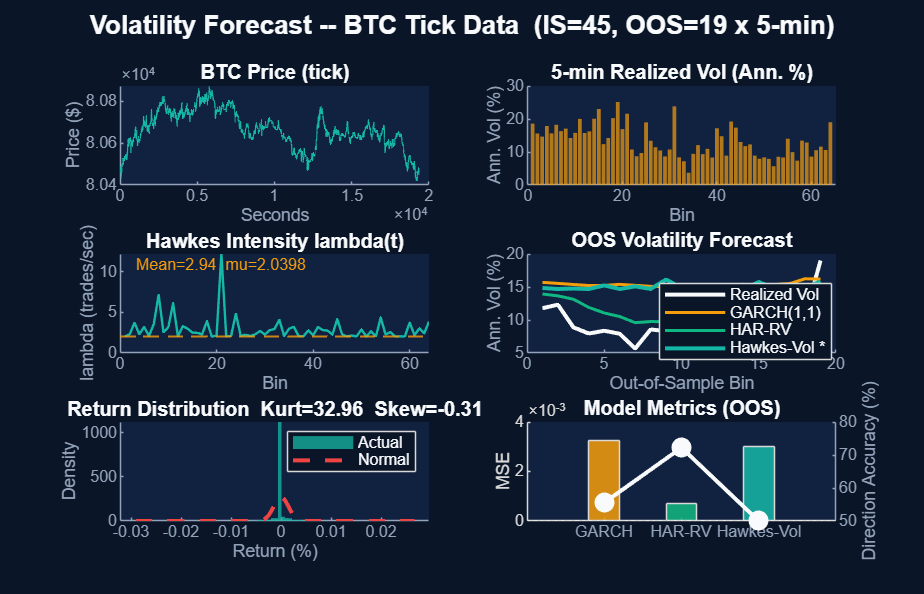


t_oos_idx = (1:n_oos)';

fig = figure('Color',BG,'Position',[50 50 1400 900]);
sgtitle(sprintf('Volatility Forecast -- BTC Tick Data  (IS=%d, OOS=%d x 5-min)', n_is, n_oos),...
    'Color',WHITE,'FontSize',13,'FontWeight','bold');

% P1: Price
ax1 = subplot(3,2,1);
set(ax1,'Color',PANEL,'XColor',GRAY,'YColor',GRAY,'FontSize',8);
hold on; box off;
plot(ts - ts(1), prices, 'Color',TEAL, 'LineWidth',0.6);
title('BTC Price (tick)', 'Color',WHITE,'FontSize',10,'FontWeight','bold');
xlabel('Seconds','Color',GRAY); ylabel('Price ($)','Color',GRAY);

% P2: RV over time
ax2 = subplot(3,2,2);
set(ax2,'Color',PANEL,'XColor',GRAY,'YColor',GRAY,'FontSize',8);
hold on; box off;
bar(1:n_bins, RV_5min_ann*100, 'FaceColor',AMBER,'EdgeColor','none','FaceAlpha',0.7);
title('5-min Realized Vol (Ann. %)', 'Color',WHITE,'FontSize',10,'FontWeight','bold');
xlabel('Bin','Color',GRAY); ylabel('Ann. Vol (%)','Color',GRAY);

% P3: Lambda over time
ax3 = subplot(3,2,3);
set(ax3,'Color',PANEL,'XColor',GRAY,'YColor',GRAY,'FontSize',8);
hold on; box off;
plot(1:n_bins, lambda_bin, 'Color',TEAL, 'LineWidth',1.2);
yline(mu_hk,'--','Color',AMBER,'LineWidth',1,'Alpha',0.8);
title('Hawkes Intensity lambda(t)', 'Color',WHITE,'FontSize',10,'FontWeight','bold');
xlabel('Bin','Color',GRAY); ylabel('lambda (trades/sec)','Color',GRAY);
text(0.05,0.88,sprintf('Mean=%.2f  mu=%.4f',mean(lambda_bin),mu_hk),...
    'Units','normalized','Color',AMBER,'FontSize',8);

% P4: OOS forecast comparison
ax4 = subplot(3,2,4);
set(ax4,'Color',PANEL,'XColor',GRAY,'YColor',GRAY,'FontSize',8);
hold on; box off;
plot(t_oos_idx, rv_actual_oos*100,   'Color',WHITE, 'LineWidth',2,   'DisplayName','Realized Vol');
plot(t_oos_idx, sigma_garch_oos*100, 'Color',AMBER, 'LineWidth',1.5, 'DisplayName','GARCH(1,1)');
plot(t_oos_idx, rv_hat_har*100,      'Color',GREEN, 'LineWidth',1.5, 'DisplayName','HAR-RV');
plot(t_oos_idx, sigma_hv_oos*100,    'Color',TEAL,  'LineWidth',2,   'DisplayName','Hawkes-Vol *');
title('OOS Volatility Forecast', 'Color',WHITE,'FontSize',10,'FontWeight','bold');
xlabel('Out-of-Sample Bin','Color',GRAY); ylabel('Ann. Vol (%)','Color',GRAY);
legend('TextColor',WHITE,'Color',BG,'FontSize',8,'Location','best');

% P5: Return distribution
ax5 = subplot(3,2,5);
set(ax5,'Color',PANEL,'XColor',GRAY,'YColor',GRAY,'FontSize',8);
hold on; box off;
ret_all = diff(log(prices));
histogram(ret_all*100, 80, 'FaceColor',TEAL,'EdgeColor','none','FaceAlpha',0.75,'Normalization','pdf');
x_n = linspace(min(ret_all)*100, max(ret_all)*100, 300);
plot(x_n, normpdf(x_n, mean(ret_all)*100, std(ret_all)*100),...
    'Color',RED,'LineWidth',2,'LineStyle','--');
title(sprintf('Return Distribution  Kurt=%.2f  Skew=%.2f',...
    kurtosis(ret_all), skewness(ret_all)),...
    'Color',WHITE,'FontSize',10,'FontWeight','bold');
xlabel('Return (%)','Color',GRAY); ylabel('Density','Color',GRAY);
legend('Actual','Normal','TextColor',WHITE,'Color',BG,'FontSize',8);

% P6: Model metrics bar
ax6 = subplot(3,2,6);
set(ax6,'Color',PANEL,'XColor',GRAY,'YColor',GRAY,'FontSize',8);
hold on; box off;
model_names = {'GARCH','HAR-RV','Hawkes-Vol'};
mses = [mse_garch, mse_har, mse_hv];
dirs = [dir_garch, dir_har, dir_hv]*100;
plot_cols = {AMBER, GREEN, TEAL};
for i = 1:3
    bar(i, mses(i), 0.4, 'FaceColor',plot_cols{i}, 'FaceAlpha',0.85);
end
set(ax6,'XTick',1:3,'XTickLabel',model_names,'YColor',GRAY);
ylabel('MSE','Color',GRAY);
yyaxis right;
plot(1:3, dirs, 'o-','Color',WHITE,'LineWidth',2,'MarkerSize',8,'MarkerFaceColor',WHITE);
yline(50,':','Color',WHITE,'Alpha',0.5,'LineWidth',1);
ylabel('Direction Accuracy (%)','Color',GRAY);
set(ax6,'YColor',GRAY);
title('Model Metrics (OOS)', 'Color',WHITE,'FontSize',10,'FontWeight','bold');

saveas(fig, [RES 'vol_forecast_eval.png']);

fprintf('  Saved: vol_forecast_eval.png\n');

  Saved: vol_forecast_eval.png



%% 10. Save
RV.bins_5min   = n_bins;
RV.RV_5min_ann = RV_5min_ann;
RV.ret_5min    = ret_5min;
RV.lambda_bin  = lambda_bin;
RV.daily_ann   = RV_5min_ann;   % alias for downstream
RV.sigma_hist  = mean(RV_5min_ann);
save([RES 'rv_data.mat'], 'RV');

vol_eval.garch_mse = mse_garch; vol_eval.garch_mae = mae_garch; vol_eval.garch_dir = dir_garch;
vol_eval.har_mse   = mse_har;   vol_eval.har_mae   = mae_har;   vol_eval.har_dir   = dir_har;
vol_eval.hv_mse    = mse_hv;    vol_eval.hv_mae    = mae_hv;    vol_eval.hv_dir    = dir_hv;
vol_eval.n_oos = n_oos; vol_eval.n_is = n_is;
save([RES 'vol_eval_results.mat'], 'vol_eval');

fprintf('\n=========================================\n');

fprintf('  Phase 2A Complete!\n');

  Phase 2A Complete!


fprintf('  Hawkes-Vol: MSE=%.4f  Dir=%.1f%%\n', mse_hv, dir_hv*100);

  Hawkes-Vol: MSE=0.0030  Dir=50.0%


fprintf('=========================================\n');